# Application: State and Output Trajectories of LTI Systems using  the Control System Toolbox - Example 2

## Introduction

The *Control System Toolbox* provides a set of functions with which it is possible to simulate the free and forced state and output response for an LTI system and obtain plots of the newly calculated state and output response.

Typically, the steps are:

- Assign the starting and ending time instant for the numerical evaluation of the state and/or output response.

- Assign the initial state.

- In case a set of inputs is needed (forced response, for example), compute the values of the inputs for some given time samples.

- Define the LTI system and evaluate the free, the forced or both state and/or output responses.

- Plot the results.

- Analyse the results.

### With a Little Help from the 'help' Command

help ss

 ss - State-space model
    Use ss to create real-valued or complex-valued state-space models, or to
    convert dynamic system models to state-space model form.

    Creation
      Syntax
        sys = ss(A,B,C,D)
        sys = ss(A,B,C,D,ts)
        sys = ss(A,B,C,D,ltiSys)
        sys = ss(D)
        sys = ss(___,Name,Value)

        sys = ss(ltiSys)
        sys = ss(ltiSys,component)

        sys = ss(ssSys,'minimal')
        sys = ss(ssSys,'explicit')

      Input Arguments
        A - State matrix
          Nx-by-Nx matrix
        B - Input-to-state matrix
          Nx-by-N

help tf

 tf - Transfer function model
    Use tf to create real-valued or complex-valued transfer function models,
    or to convert dynamic system models to transfer function form.

    Creation
      Syntax
        sys = tf(numerator,denominator)
        sys = tf(numerator,denominator,ts)
        sys = tf(numerator,denominator,ltiSys)

        sys = tf(m)

        sys = tf(___,Name,Value)

        sys = tf(ltiSys)
        sys = tf(ltiSys,component)

        s = tf('s')
        z = tf('z',ts)

      Input Arguments
        numerator - Numerator coefficients of the transfer function
          row vector | Ny-by-Nu cell array of row vectors
        


help zpk

 zpk - Zero-pole-gain model
    Use zpk to create zero-pole-gain models, or to convert dynamic system
    models to zero-pole-gain form.

    Creation
      Syntax
        sys = zpk(zeros,poles,gain)
        sys = zpk(zeros,poles,gain,ts)
        sys = zpk(zeros,poles,gain,ltiSys)

        sys = zpk(m)

        sys = zpk(___,Name,Value)

        sys = zpk(ltiSys)
        sys = zpk(ltiSys,component)

        s = zpk('s')
        z = zpk('z',ts)

      Input Arguments
        zeros - Zeros of the zero-pole-gain model
          row vector | Ny-by-Nu cell array of row vectors
        p


help initial

 initial - System response to initial states of state-space model
    For state-space and sparse state-space models, initial computes the
    unforced system response y to initial states xinit.

    Syntax
      [y,tOut] = initial(sys,IC)
      [y,tOut] = initial(sys,IC,t)
      [y,tOut] = initial(sys,IC,t,p)
      [y,tOut,x] = initial(___)
      [y,tOut,x,pOut] = initial(sys,IC,t,p)

      initial(___)

    Input Arguments
      sys - Dynamic state-space model
        dynamic state-space model | model array
      t - Time steps
        positive scalar | two-element vector | vector | []
     

help initialplot

--- help for controllib.chart.InitialPlot ---

 controllib.chart.InitialPlot - Plot initial condition response of dynamic system
    The initialplot function plots the initial condition response of a
    dynamic system model and returns an InitialPlot chart object.

    Creation
      Syntax
        ip = initialplot(sys,IC)
        ip = initialplot(sys1,sys2,...,sysN,x0)
        ip = initialplot(sys1,LineSpec1,...,sysN,LineSpecN,x0)
        ip = initialplot(___,t)
        ip = initialplot(sys,IC,t,p)

        ip = initialplot(___,plotoptions)

        ip = initialplot(parent,___)

      Input Arguments
        sys - Dynamic system
          dynamic system model | model array
        


help lsim

 lsim - Compute time response simulation data of dynamic system to arbitrary inputs
    This MATLAB function returns the system response y to the input u,
    sampled at the same times t as the input.

    Response Data
      y = lsim(sys,u,t)
      y = lsim(sys,u,t,IC)
      y = lsim(sys,u,t,IC,p)
      [y,tOut] = lsim(___)
      [y,tOut,x] = lsim(___)
      [y,tOut,x,pOut] = lsim(sys,u,t,IC,p)

    Input Interpolation Method
      [___] = lsim(___,method)

    State Snapshot POD
      [y,tOut,x,~,xPODOut] = lsim(___,xPODIn)
      [y,tOut,x,~,xPODOut] = lsim(___,xPODIn,method)

    Response Plots
      lsim(___)

    Linear Simulation Tool
      lsim(sys)

    Input Arguments
      

help lsimplot

--- help for controllib.chart.LSimPlot ---

 controllib.chart.LSimPlot - Plot simulated time response of dynamic system to arbitrary inputs
    The lsimplot function plots the simulated time response of a dynamic
    system model to arbitrary inputs and returns an LSimPlot chart object.

    Creation
      Syntax
        lp = lsimplot(___,method)

        lp = lsimplot(sys,u,t)
        lp = lsimplot(sys1,sys2,...,sysN,u,t)
        lp = lsimplot(sys1,LineSpec1,...,sysN,LineSpecN,u,t)
        lp = lsimplot(___,IC)
        y = lsim(sys,u,t,IC,p)

        lp = lsimplot(___,plotoptions)

        lp = lsimplot(parent,___)

        lp = lsimplot(sys)
        lp = lsimplot(sys1,sys2,...,sysN)
        lp = lsimplot(sys1,LineSpec1,...,sysN,LineSpecN)

      Input Arguments
        sys - Dynamic system
          dynamic 


help step

 step - Step response of dynamic system
    step computes the step response to a step change in input value from U
    to U + dU after td time units.

    Syntax
      [y,tOut] = step(sys)
      [y,tOut] = step(sys,t)
      [y,tOut] = step(sys,t,p)
      [y,tOut,x] = step(___)
      [y,tOut,x,ysd] = step(___)
      [y,tOut,x,~,pOut] = step(sys,t,p)

      [y,tOut] = step(___,config)

      step(___)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      t - Time steps
        positive scalar | two-element vector | vector | 

help RespConfig

 RespConfig - Options for step or impulse responses
    Use a RespConfig object to specify options for plotting step responses
    (step, stepplot), impulse responses (impulse, impulseplot), and initial
    responses (initial and initialplot).

    Creation
      Syntax
        respOpt = RespConfig
        respOpt = RespConfig(Name=Value)

    Properties
      Bias - Baseline input signal value
        0 (default) | scalar | vector | 'u0'
      Amplitude - Input level change
        1 (default) | scalar | vector
      Delay - Step or impulse delay
        0 (default) | nonnegative scalar
      


help stepplot

--- help for controllib.chart.StepPlot ---

 controllib.chart.StepPlot - Plot step response of dynamic system
    The stepplot function plots the step response of a dynamic system model
    and returns a StepPlot chart object.

    Creation
      Syntax
        sp = stepplot(sys)
        sp = stepplot(sys1,sys2,...,sysN)
        sp = stepplot(sys1,LineSpec1,...,sysN,LineSpecN)
        sp = stepplot(___,t)
        sp = stepplot(___,t,p)

        sp = stepplot(___,config)

        sp = stepplot(___,plotoptions)

        sp = stepplot(parent,___)

      Input Arguments
        sys - Dynamic system
          dynamic system model | model array
        <a href="matlab:web /Applications/MATLAB_R2024b.app/help/control/ref/controllib.chart.stepplot.html#f4-462928_sep_mw_ea9bcb72-a5ae-4762-ad44-8c43c10f5370">LineSpec</a


help stepinfo

 stepinfo - Rise time, settling time, and other step-response characteristics
    stepinfo lets you compute step-response characteristics for a dynamic
    system model or for an array of step-response data.

    Syntax
      S = stepinfo(sys)

      S = stepinfo(y,t)
      S = stepinfo(y,t,yfinal)
      S = stepinfo(y,t,yfinal,yinit)

      S = stepinfo(___,'SettlingTimeThreshold',ST)
      S = stepinfo(___,'RiseTimeLimits',RT)

    Input Arguments
      sys - Dynamic system
        dynamic system model
      y - Step-response data
        vector | array
      

## LTI System of 2nd Order: the Cart-Spring-Damper Example

We want to determine state and output trajectories for the LTI system:

        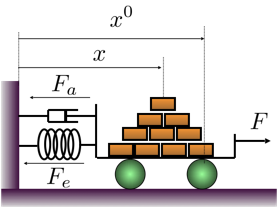     


$$\left\{ \begin{array}{rcl}
\dot{x_1}(t) &=& x_2(t)\\
\dot{x_2}(t) &=& -\frac{k}{M} x_1(t) - \frac{h}{M} x_2(t) +\frac{1}{M} u(t) \\
y(t) &=& x_1(t) 
\end{array} \right.$$


with initial condition $x_1(0) = x_0\,,\; x_2(0) = v_0$ and input $u(t) = 1+A \cos(\omega t) \cdot 1(t)\,$

### Step 1: Starting and Ending Time Instant

clear

% -------- starting & ending time instants -------
minTstart = 0; maxTstart = 10; % min & max admissible vales for Tstart
minDuration = 20;              % min value for the interval (Tfinal-Tstart)

minTfinal = minTstart+minDuration; % min value for Tfinal
maxTfinal = 100;                   % max value for Tfinal

Tstart = 0;  % the initial time instant
dummyT = min(Tstart, maxTstart) + minDuration;
Tfinal = 300; % the final time instant
% -------- starting & ending time instants -------


#### Step 2: The Initial State & System Parameters

**The Initial State**

Modify the initial position $x(0)$ and the initial speed $\dot{x}(0)$ of the cart and analyse the result


init_pos   = -3; % initial position [m]
init_speed = 10; % initial speed [m/s]

x0VAL = [init_pos; init_speed];

**System Parameters**

k_bar = 10.09; % N/m <-- nominal value  of the spring elastic constant

Mval = 123.52;  % kg [cart mass]
hval = 9.12;   % Ns/m [damping constant]
kval = 10.89; %k_bar;   % N/m [spring elastic coeff.] <-- change the value; use for instance k = 10.89    
% using this set of params --> roots([M h k]) complex conj.
% 

### Step 3: The Inputs

% ---- input parameters ----
Aval = 40.50;      % magnitude of the external input force u [N]
OMval = 2*pi*0.05; % angular frequency of the input [rad/s]
% ---- input parameters ----

% --- computing samples of the input time function ----
t = (Tstart:1e-3:Tfinal); % a set of time instants
u = Aval * cos(OMval * t)+1; % the corresponding values of the input
% Note: you DO NOT NEED to explicity write the Heaviside function!


### Step 4: Evaluate the State & Output Responses

The LTI system is described by the following state space LTI object

matA = [    0            1;
       -kval/Mval  -hval/Mval];  % the matrix A in x_dot = Ax + Bu

matB = [   0; 
        1/Mval]; % the matrix B in x_dot = Ax + Bu

matC = [1 0];    % the matrix C in     y = Cx + Du

matD = 0;        % the matrix C in     y = Cx + Du

sysCART = ss(matA, matB, matC, matD)


sysCART =
 
  A = 
             x1        x2
   x1         0         1
   x2  -0.08816  -0.07383
 
  B = 
             u1
   x1         0
   x2  0.008096
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


#### Free State & Output Responses Only

[Y1free, ~, X1free] =  initial(sysCART, x0VAL, t); 
% samples of the free state & output responses

####  Forced State & Output Responses Only

[Y1forced, ~, X1forced ] = lsim(sysCART, u, t);
% samples of the forced state & output responses


#### All at Once 

[Y1full, ~, X1full] = lsim(sysCART, u, t, x0VAL); % <-- Note: the initial state!

### Step 5: Plot the results.

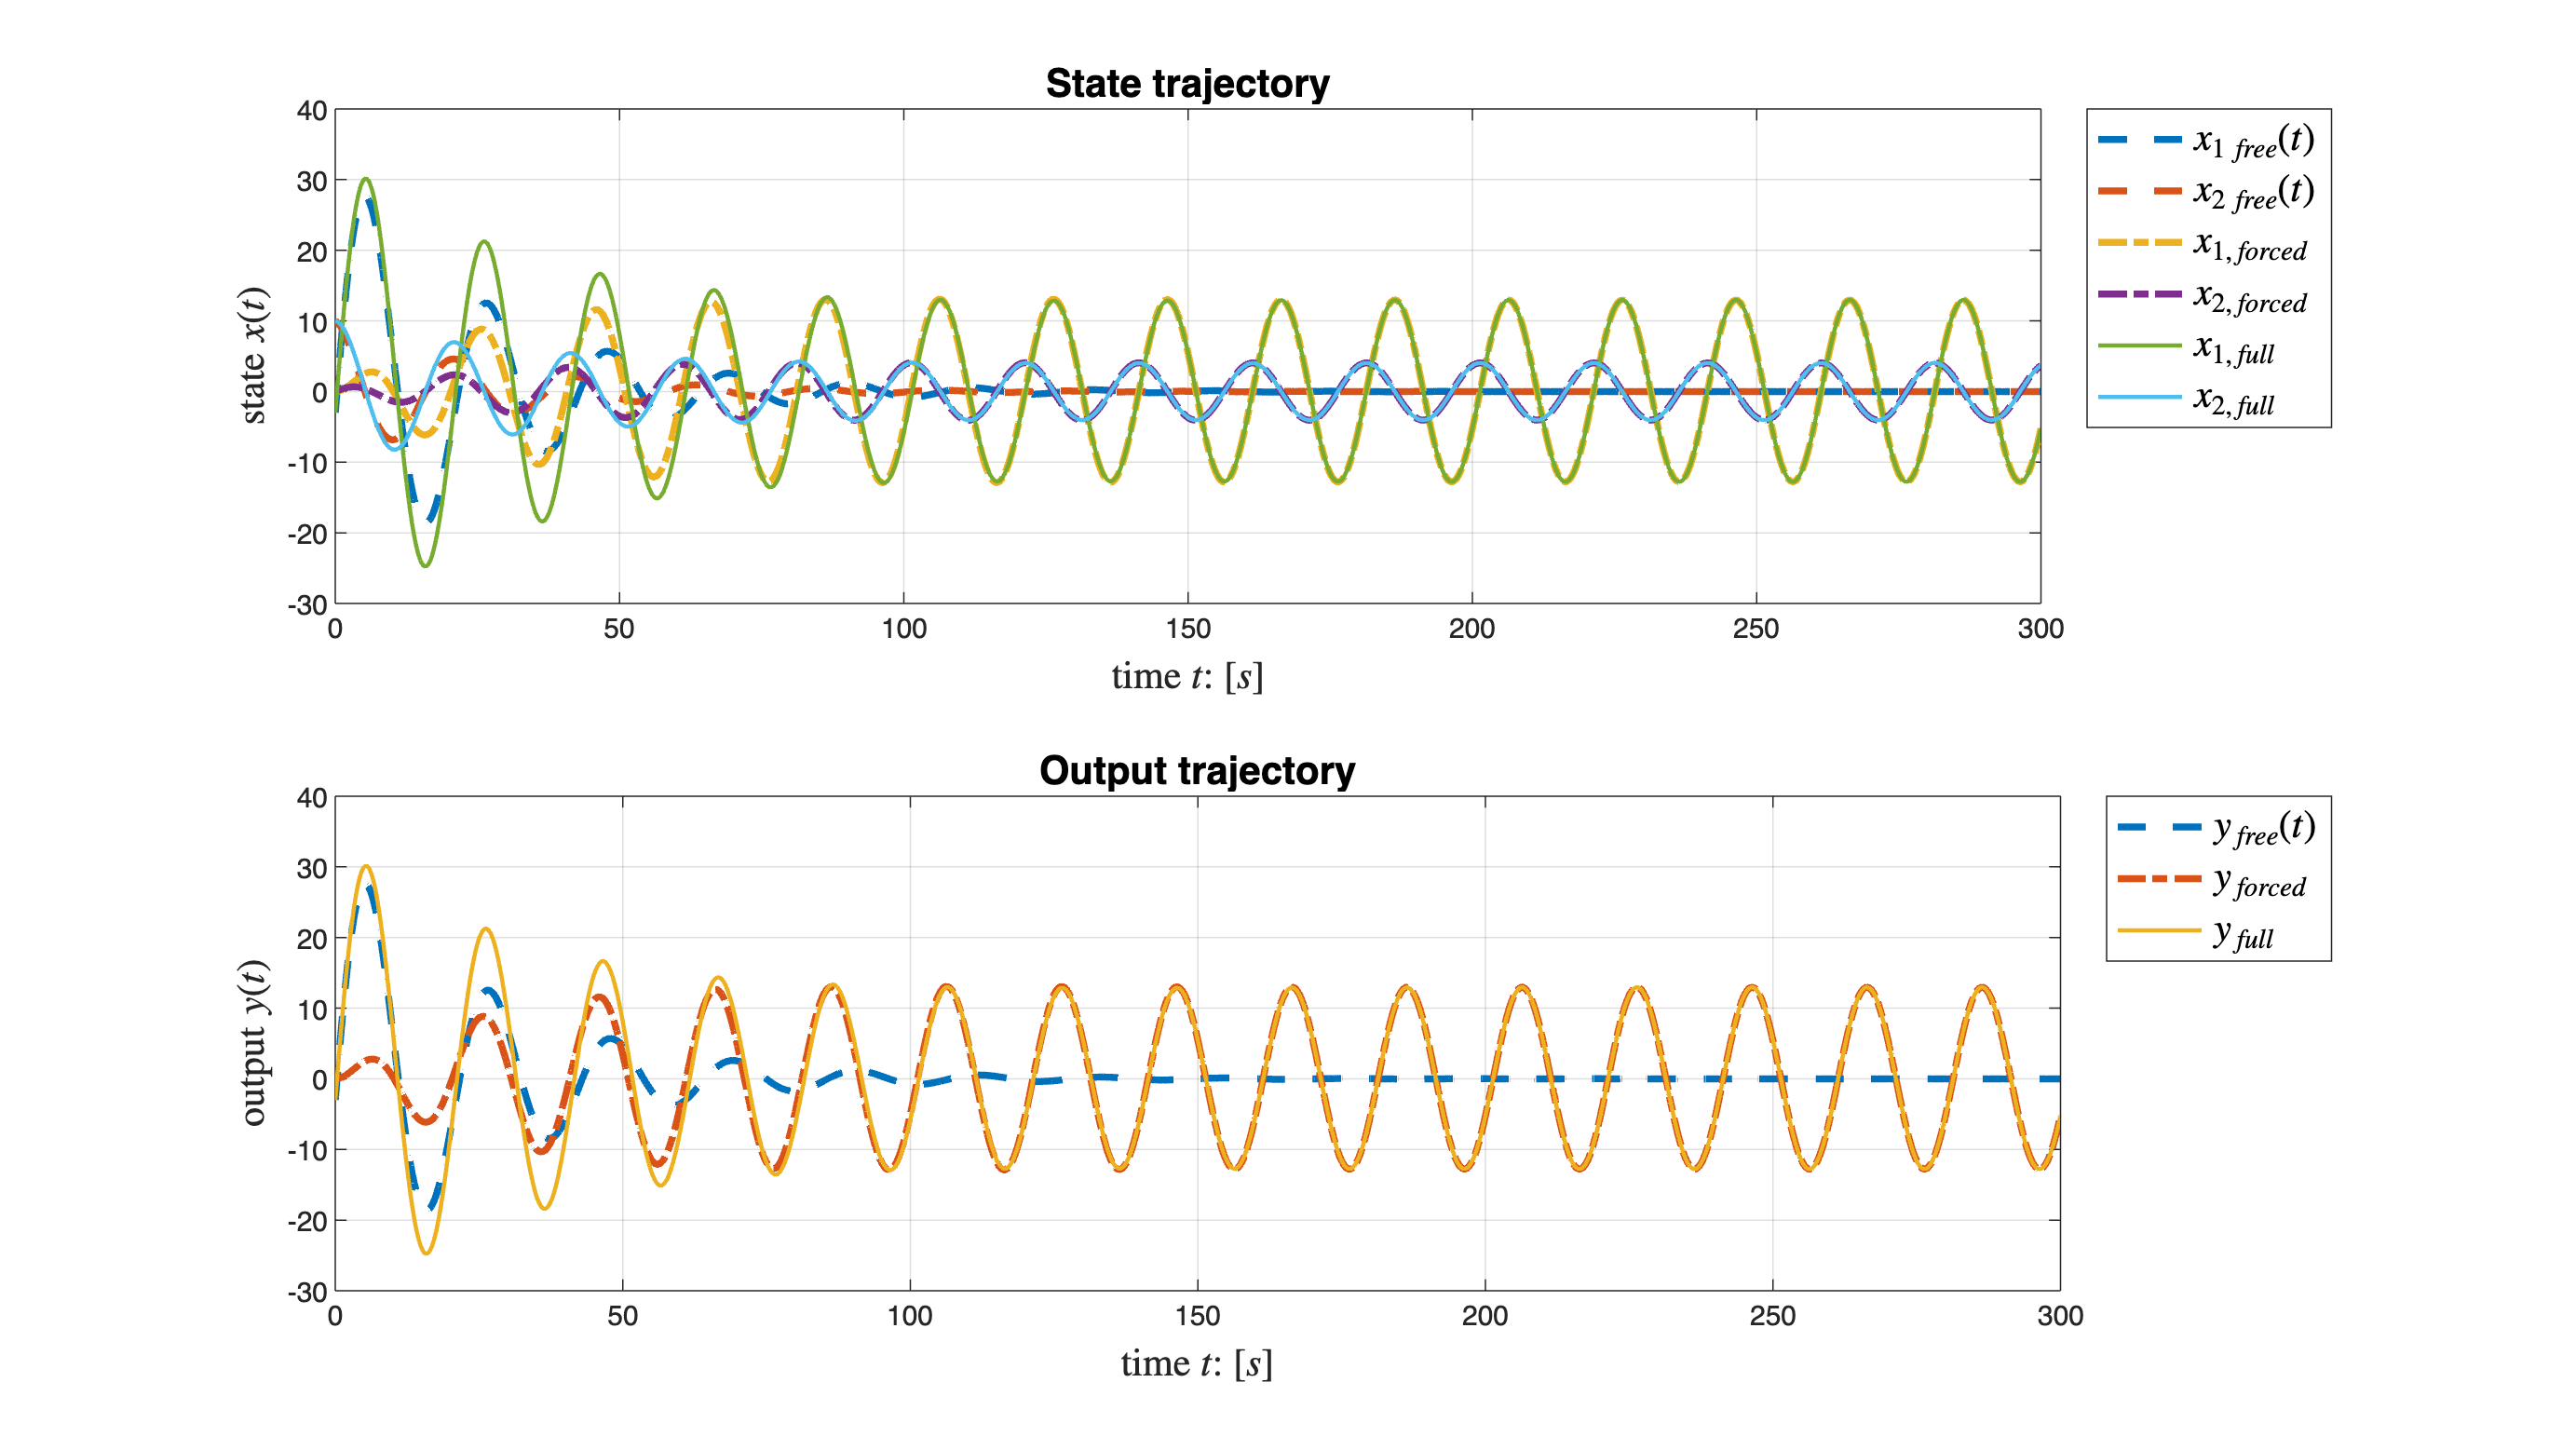

figure('Units','normalized','Position',[0.1,0.1,0.9,0.9])

subplot(2,1,1)

plot(t, X1free, 'LineStyle','--', 'LineWidth',2.5);
hold on
plot(t, X1forced, 'LineStyle','-.', 'LineWidth',2.5);
plot(t, X1full, 'LineStyle','-', 'LineWidth',1.5);

legend('$x_{1\,free}(t)$','$x_{2\,free}(t)$', ...
        '$x_{1,forced}$','$x_{2,forced}$', ...
        '$x_{1,full}$', '$x_{2,full}$',...
        'Interpreter', 'latex', 'Fontsize', 14, 'Location', 'bestoutside');

xlabel('time $t$: [$s$]', 'Interpreter', 'latex', 'fontsize',14);
ylabel(' state $x(t)$', 'Interpreter', 'latex', 'fontsize',14);
title('State trajectory', 'fontsize',14);
xlim([Tstart, Tfinal])
grid on

subplot(2,1,2);
plot(t, Y1free, 'LineStyle','--', 'LineWidth',2.5);
hold on
plot(t, Y1forced, 'LineStyle','-.', 'LineWidth',2.5);
plot(t, Y1full, 'LineStyle','-', 'LineWidth',1.5);

legend('$y_{free}(t)$', '$y_{forced}$', '$y_{full}$', ...
    'Interpreter', 'latex', 'Fontsize', 14, 'Location', 'bestoutside');
           
title('Output trajectory','fontsize',14);
xlabel('time $t$: [$s$]', 'Interpreter', 'latex', 'fontsize',14);
ylabel('output $y(t)$', 'Interpreter', 'latex', 'fontsize',14);
xlim([Tstart, Tfinal])
grid on